# Pencil Sketch Effect

Sherry Zhou

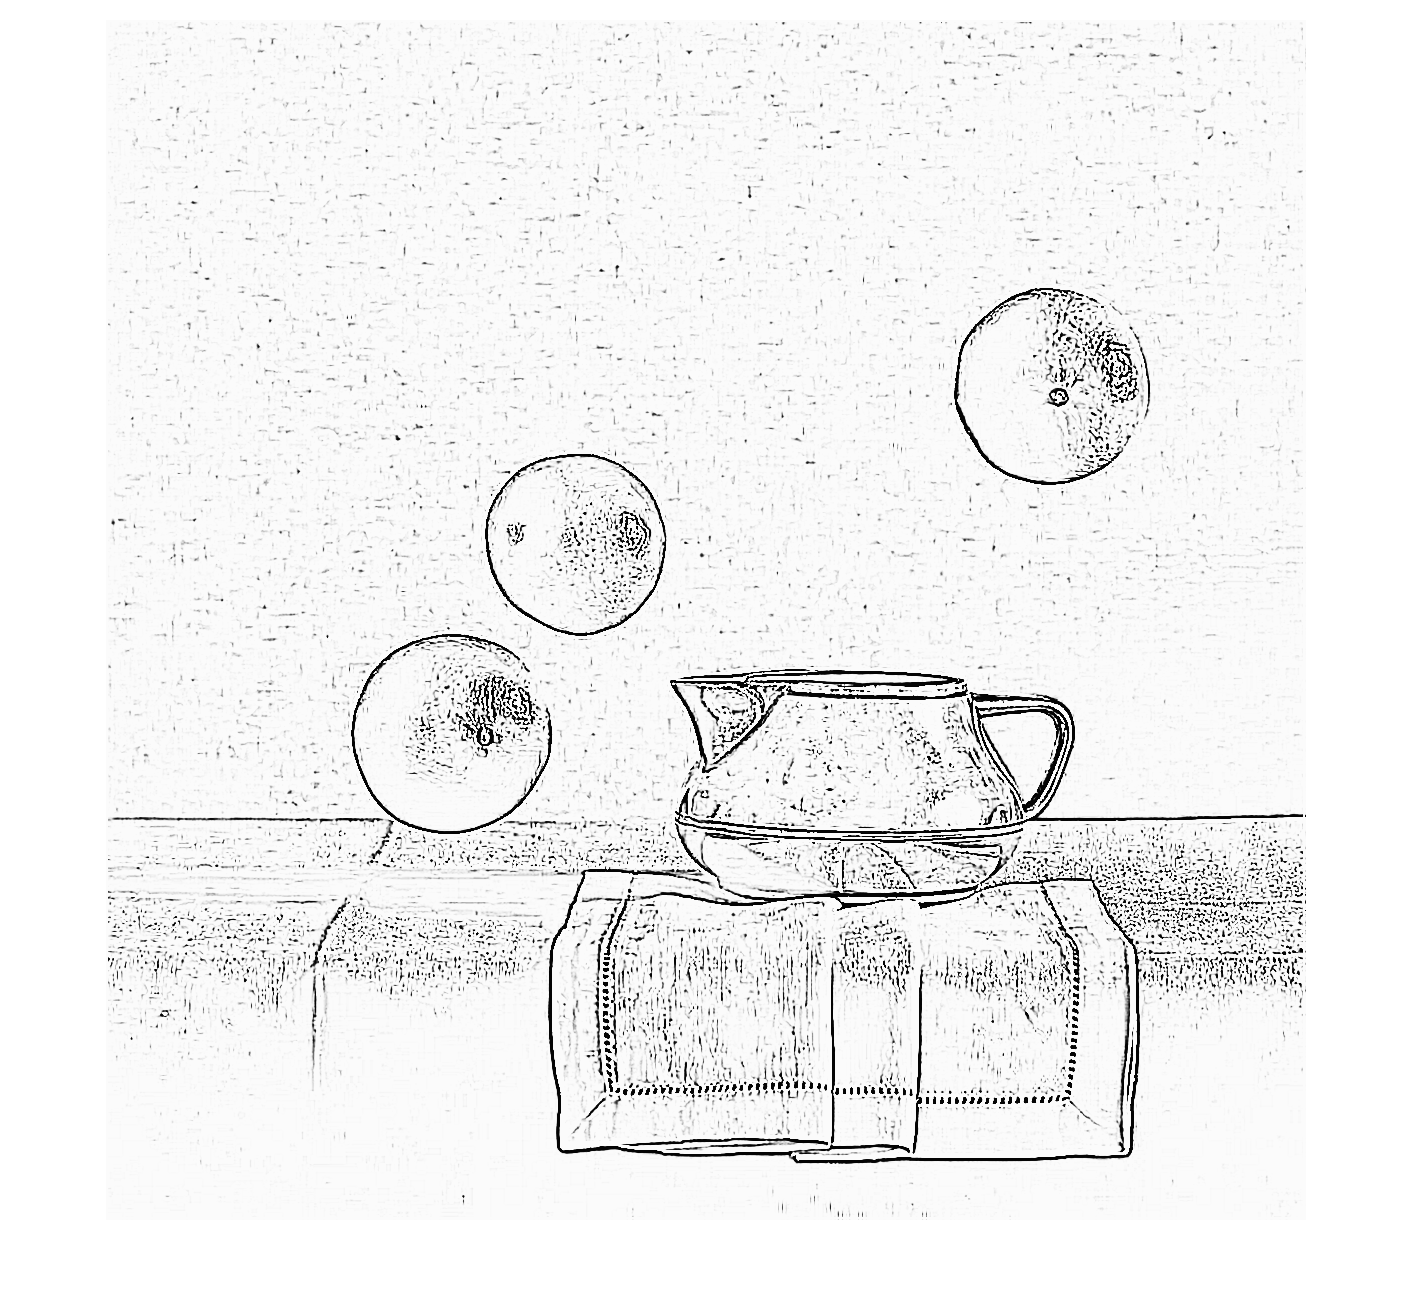

clear;clc;close all;

I = imread('still.jpeg');
IG = rgb2gray(I);

% Laplacian 8-connected edge detector applied over a larger region
h2 =   [1 1 1 1 1 1;
    1 1 1 1 1 1;
    1 1 -8 -8 1 1;
    1 1 -8 -8 1 1;
    1 1 1 1 1 1;
    1 1 1 1 1 1]; % edges 8 2blocks
imag = imfilter( IG, h2, 'conv');

% invert the color
imagf = 255-imag;

% Contrast Stretching
imagf = double(imagf) / 255; 
c_contrast = 8 ; % c parameter for contrast stretching transformation
imagf_contrast = 1 ./ (1 + exp(-c_contrast * (imagf - 0.5))) ;
imshow(imagf_contrast)